# [3.10. Емкость](https://ru.wikipedia.org/wiki/%D0%AD%D0%BB%D0%B5%D0%BA%D1%82%D1%80%D0%B8%D1%87%D0%B5%D1%81%D0%BA%D0%B0%D1%8F_%D1%91%D0%BC%D0%BA%D0%BE%D1%81%D1%82%D1%8C)

#### Определение емкости

clear
syms C Q V
C==Q/V

$$ans = C=\frac{Q}{V}$$

#### [Плоский конденсатор](https://ru.wikipedia.org/wiki/%D0%AD%D0%BB%D0%B5%D0%BA%D1%82%D1%80%D0%B8%D1%87%D0%B5%D1%81%D0%BA%D0%B8%D0%B9_%D0%BA%D0%BE%D0%BD%D0%B4%D0%B5%D0%BD%D1%81%D0%B0%D1%82%D0%BE%D1%80)

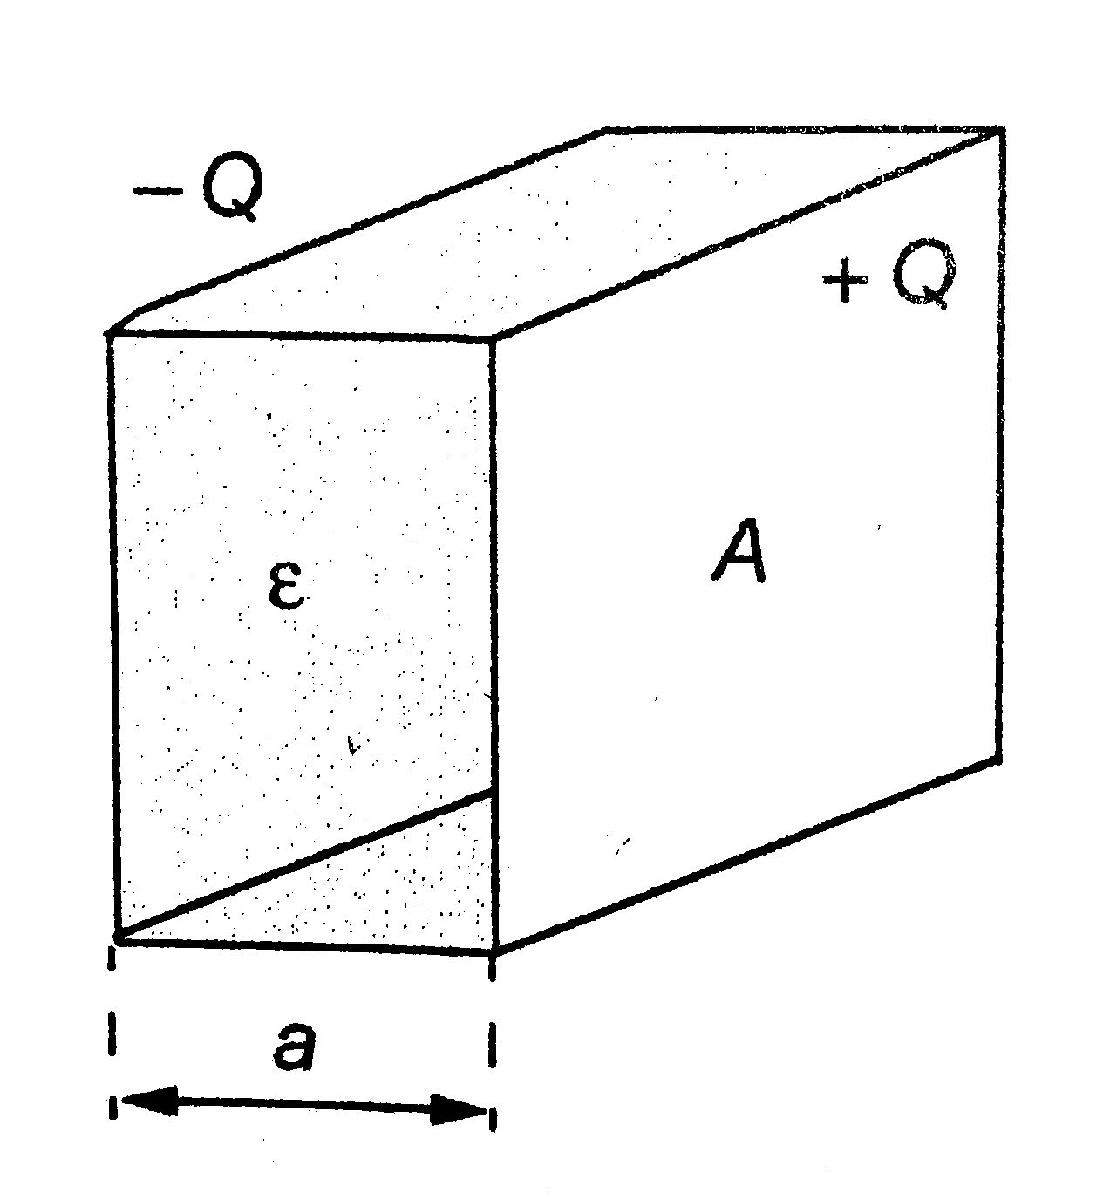

syms C epsilon epsilon0 A a
C==epsilon*epsilon0*A/a

$$ans = C=\frac{A\,\epsilon \,\epsilon_{0}}{a}$$

Сила взаимодействия пластин

syms F W_C(a) Q
F==diff(W_C,a)==Q^2/(2*epsilon*epsilon0*A)

$$ans(a) = \left(F=\frac{\partial }{\partial a}W_{C}\left(a\right)\right)=\frac{Q^{2}}{2\,A\,\epsilon \,\epsilon_{0}}$$

#### Цилиндрический конденсатор

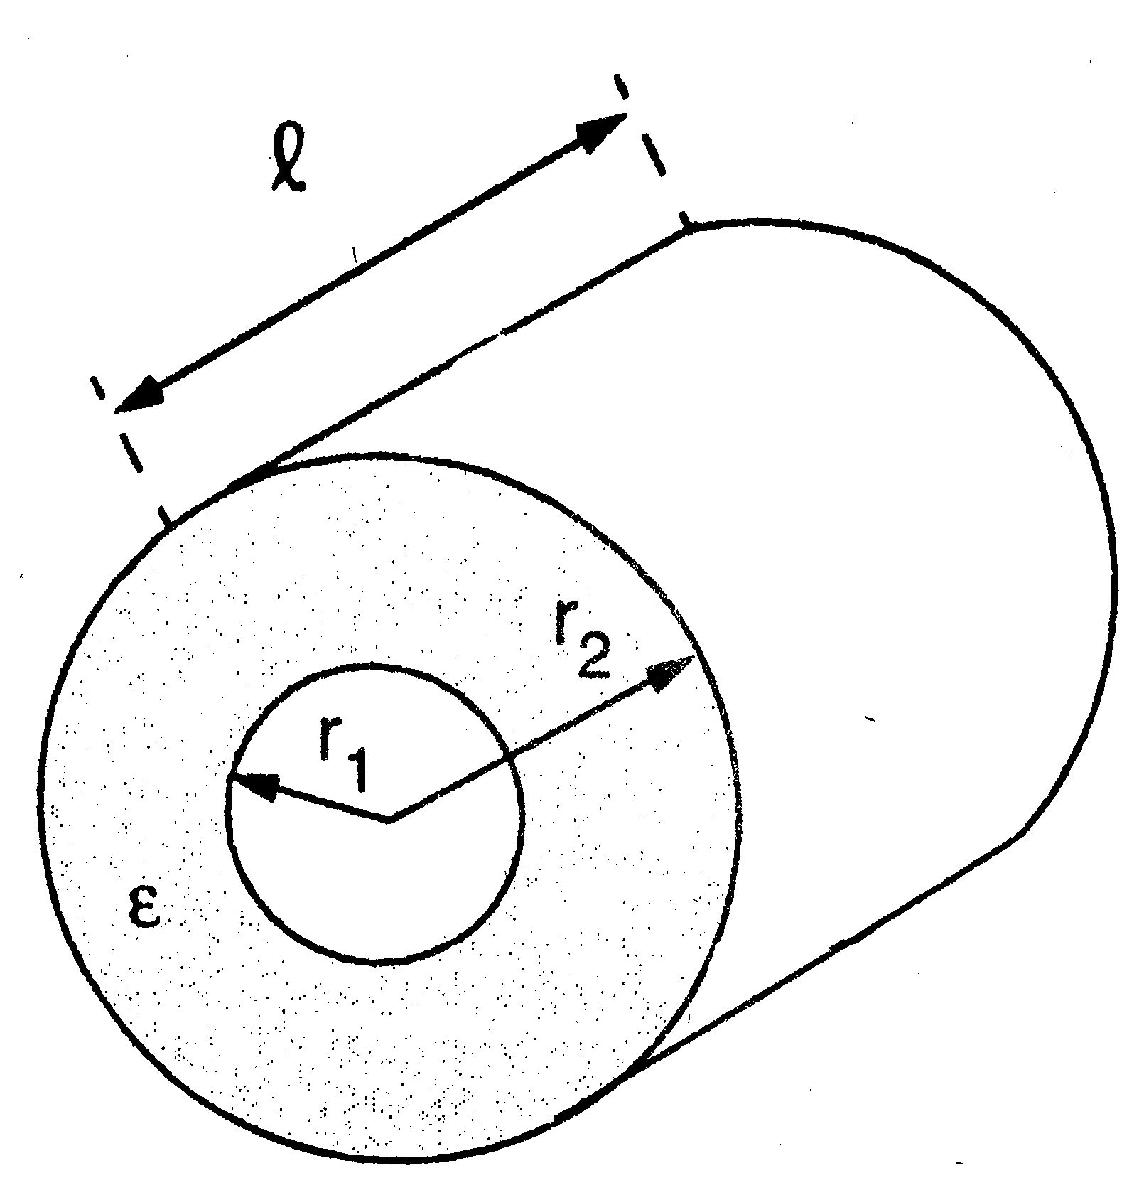

syms C epsilon epsilon0  L r1 r2
C==epsilon*epsilon0*(2*pi*L)/log(r2/r1)

$$ans = C=\frac{2\,\pi \,L\,\epsilon \,\epsilon_{0}}{\log\left(\frac{r_{2}}{r_{1}}\right)}$$

#### Сферический конденсатор

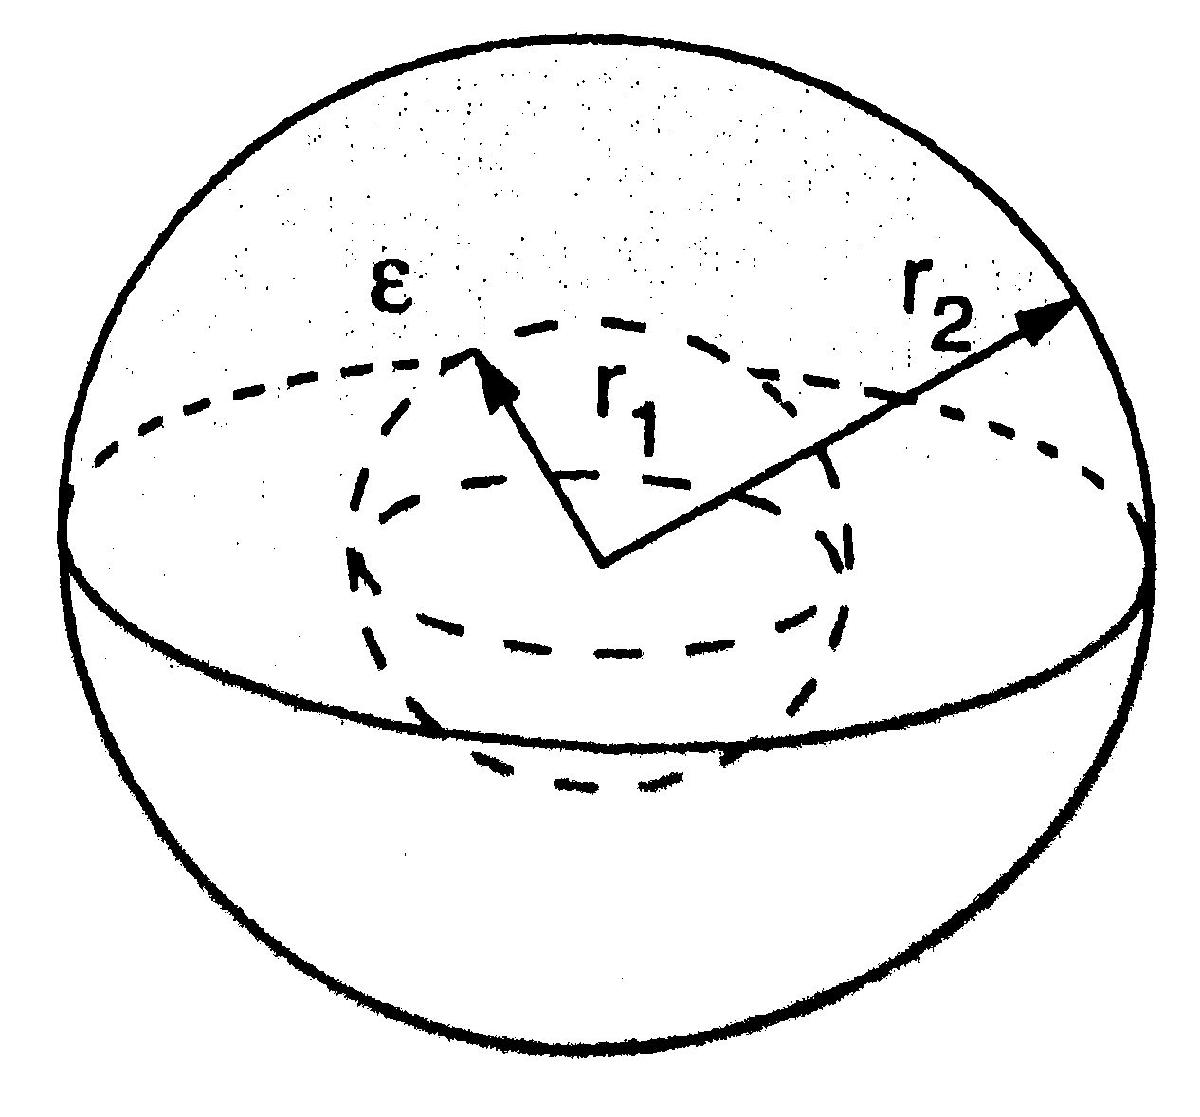

C==epsilon*epsilon0*(4*pi*r1*r2)/(r2-r1)

$$ans = C=-\frac{4\,\pi \,\epsilon \,\epsilon_{0}\,r_{1}\,r_{2}}{r_{1}-r_{2}}$$

#### Проводимость утечки

syms R sigma
1/R==sigma*C/(epsilon*epsilon0)

$$ans = \frac{1}{R}=\frac{C\,\sigma }{\epsilon \,\epsilon_{0}}$$

% sigma = удельная электропроводность диэлектрика

#### Общая емкость для последовательного и параллельного соединений

syms C_s C_p C(n)
1/C_s==symsum(1/C(n))            % последовательное соединение

$$ans = \frac{1}{C_{s}}=\sum_{n}\frac{1}{C\left(n\right)}$$

C_p==symsum(C(n))                % параллельное соединение

$$ans = C_{p}=\sum_{n}C\left(n\right)$$

#### Зарядка и разрядка конденсатора через сопротивление

syms V V_C t R C d(f,x,n)
V==V_C+R*C*d(V_C,t,1)

$$ans = V=V_{C}+C\,R\,d\left(V_{C},t,1\right)$$

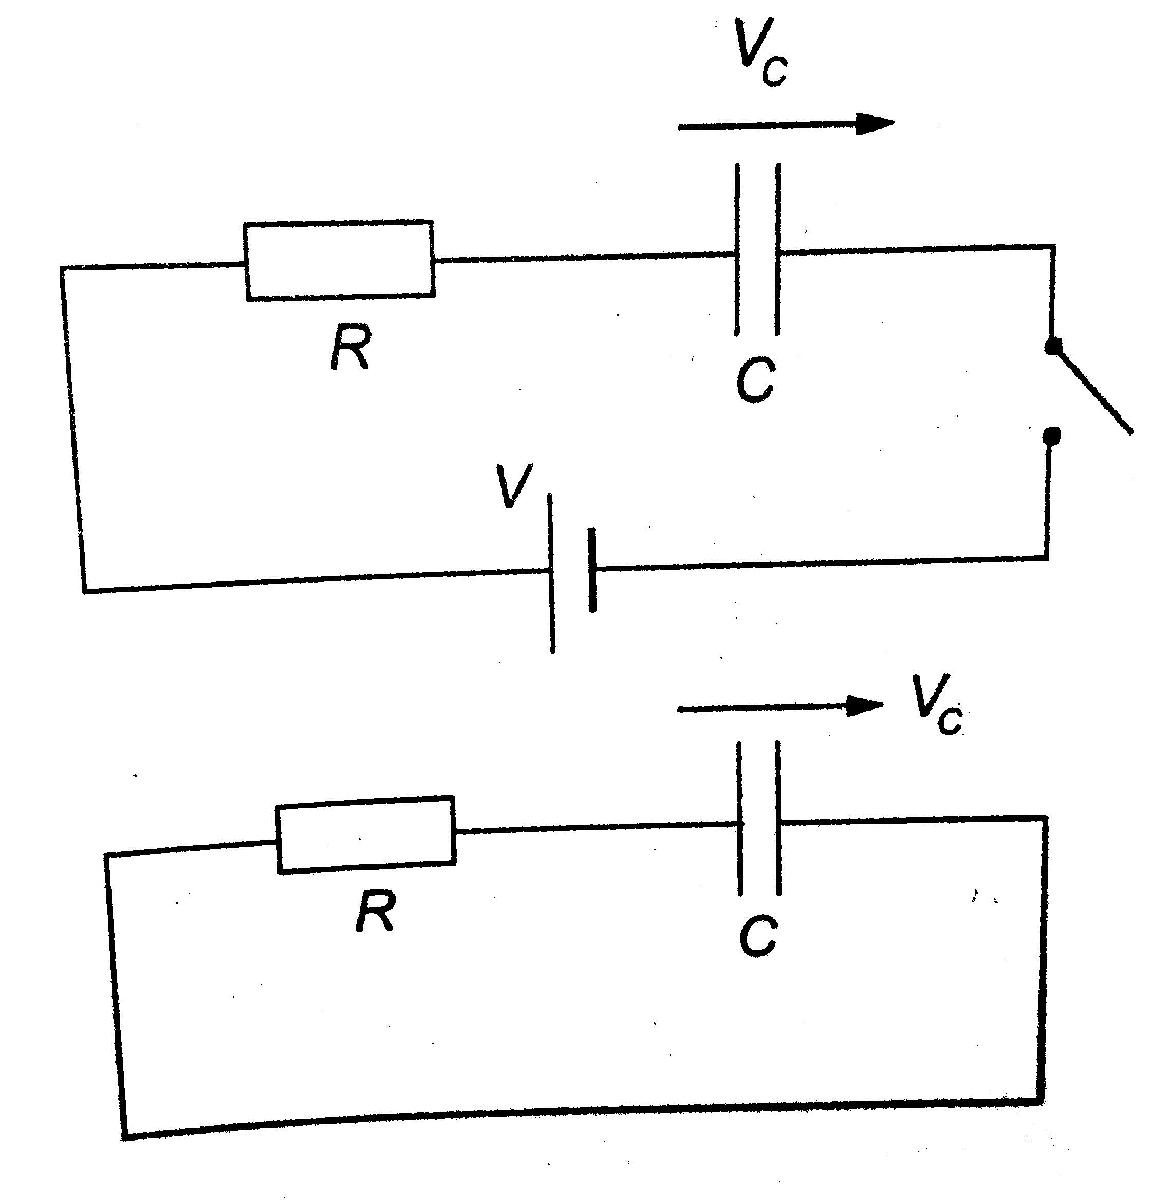

syms V_C V0
V_C==V*(1-exp(-t/(R*C)))

$$ans = V_{C}=-V\,\left({\mathrm{e}}^{-\frac{t}{C\,R}}-1\right)$$

V_C==V0*exp(-t/(R*C))

$$ans = V_{C}=V_{0}\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$

#### Энергия электрического поля в конденсаторе

syms W_C C V Q
W_C==1/2*C*V^2==1/2*Q^2/C==1/2*Q*V

$$ans = \left(\left(W_{C}=\frac{C\,V^{2}}{2}\right)=\frac{Q^{2}}{2\,C}\right)=\frac{Q\,V}{2}$$

#### [Плотность энергии](https://ru.wikipedia.org/wiki/Плотность_энергии)

syms w_c E D 
w_c==1/2*epsilon*epsilon0*E^2==1/2*D*E

$$ans = \left(w_{c}=\frac{{\text{E}}^{2}\,\epsilon \,\epsilon_{0}}{2}\right)=\frac{\text{D}\,\text{E}}{2}$$